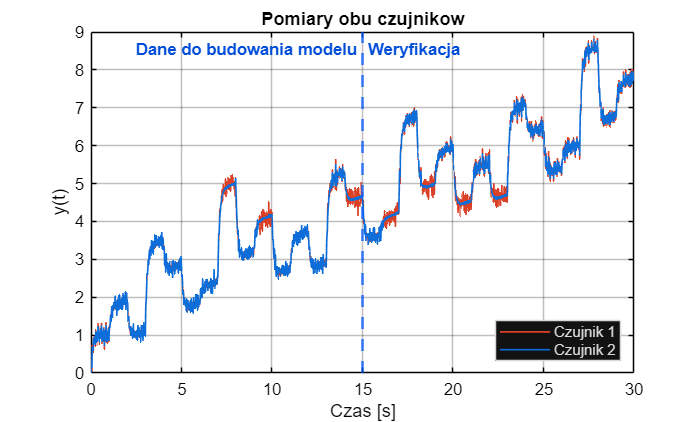

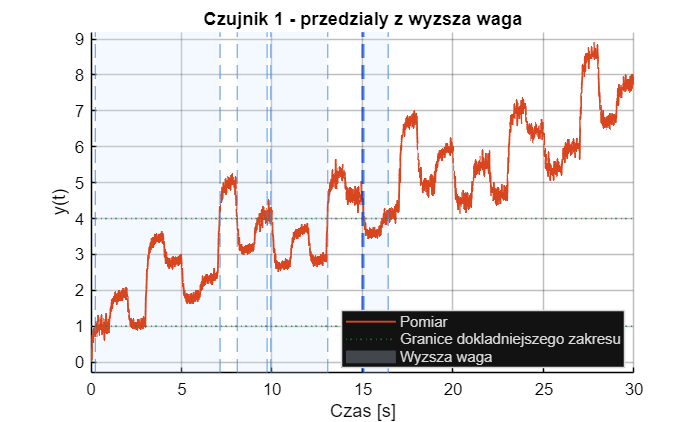

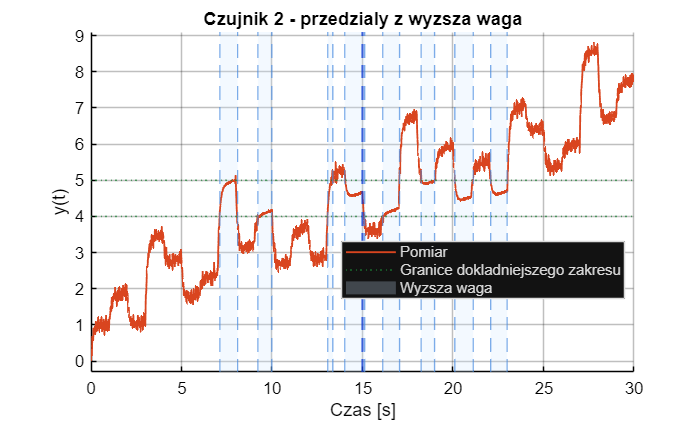


===== CZUJNIK 1 =====

MNK: a = 0.870470, b = 0.051586
G(z) = 0.051586 / (1 - 0.870470*z^-1)
G(s) = 5.926207 / (s + 14.880421)
                    mean_error      MSE       variance
                    __________    ________    ________

    Replikatywna    0.0052735     0.016712    0.016696
    Predykatywna     0.020813     0.024627     0.02421
    Calosc           0.013043      0.02067    0.020506


W10: a = 0.883131, b = 0.046463
G(z) = 0.046463 / (1 - 0.883131*z^-1)
G(s) = 5.261162 / (s + 13.233547)
                    mean_error      MSE       variance
                    __________    ________    ________

    Replikatywna     0.013047     0.013652    0.013491
    Predykatywna     0.032611     0

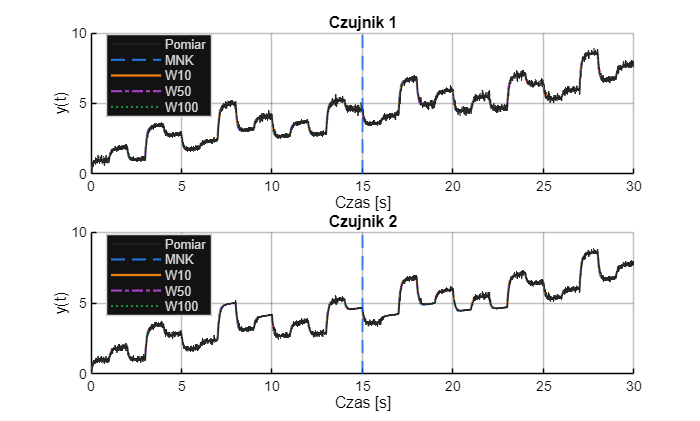

Czujnik 1 - wystarczajaca liczba probek: 66
Czujnik 2 - wystarczajaca liczba probek: 37


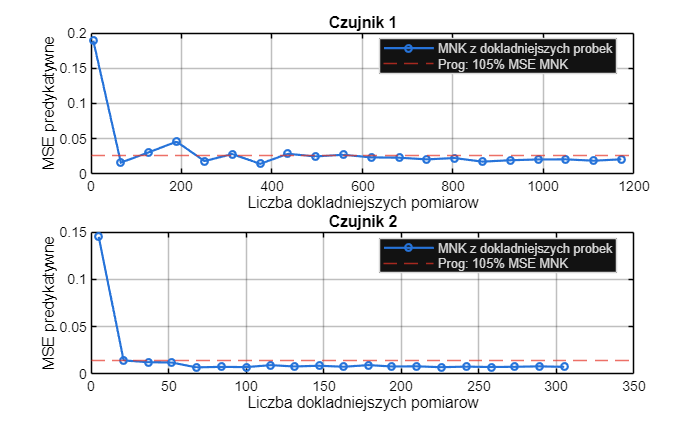

clear; clc; close all;

%% SETUP
Work_data = load('MiI_P1_grupa_1b.mat');
[sr, time, I_Data, V_Data] = Setup(Work_data);

% Parametry klasyfikacji
avg_window = 21;
tol = 0.1;
gains = [10 50 100];

[I_Data, V_Data] = weight_creator(I_Data, V_Data, gains(1), avg_window, tol);

%% OBLICZENIA
[Models_sensor1, Test_sensor1] = model_estimation(I_Data, V_Data, time, sr, 'y_cz1', gains);
[Models_sensor2, Test_sensor2] = model_estimation(I_Data, V_Data, time, sr, 'y_cz2', gains);

%% WYNIKI
present_results(time, I_Data, V_Data, Models_sensor1, Models_sensor2, Test_sensor1, Test_sensor2, gains, sr);



%% =========================================================
% Funkcje matematyczne
%% =========================================================

function [Models, Test] = model_estimation(I_Data, V_Data, time, sr, sensor_name, gains)
    % Macierz regresji i wektor obserwacji
    [H, Y, base_weights] = regression_creator(I_Data, sensor_name);
    mask = base_weights > 1;
    N_est = size(I_Data.u, 1);

    % MNK oraz trzy warianty WMNK
    for i = 1:length(gains)+1

        if i == 1
            weights = ones(size(Y));
            model_name = 'MNK';
        else
            weights = 1 + (gains(i-1)-1) * double(mask);
            model_name = sprintf('W%d', gains(i-1));
        end

        W = diag(weights);
        x = (H' * W * H) \ (H' * W * Y);

        % Transmitancja i weryfikacja
        G = tf(x(2), [1 -x(1)], sr, 'Variable', 'z^-1');
        Verification = model_verification(V_Data, sensor_name, x, N_est, time, G);

        Models(i).name = model_name;
        Models(i).x = x;
        Models(i).G = G;
        Models(i).verification = Verification;
    end

    % Estymacja tylko na dokladniejszych probkach
    Test = precise_test(H, Y, mask, V_Data, sensor_name, N_est, time, sr, ...
        Models(1).verification.predykatywna.MSE);
end

function [H, Y, w] = regression_creator(I_Data, sensor_name)
    % H = [y(k-1), u(k)]
    temp_data = I_Data.(sensor_name);
    y = temp_data(:,1);
    w = temp_data(2:end,2);
    u = I_Data.u(:);

    H = [y(1:end-1), u(2:end)];
    Y = y(2:end);
end

function Results = model_verification(V_Data, sensor_name, x, N_est, time, G)
    % Odpowiedz modelu z transmitancji
    y = V_Data.(sensor_name);
    y = y(:,1);
    u = V_Data.u(:);
    a = x(1);
    b = x(2);

    Y_sim = lsim(G, u, time);
    powers = (0:length(y)-1)';
    Y_sim = Y_sim(:) + (y(1)-b*u(1)) * a.^powers;

    % Bledy na danych identyfikacyjnych i nowych
    e_sim = y - Y_sim;
    Results.replikatywna = error_metrics(e_sim(2:N_est));
    Results.predykatywna = error_metrics(e_sim(N_est+1:end));
    Results.calosc = error_metrics(e_sim(2:end));
    Results.Y_sim = Y_sim;
end

function Metrics = error_metrics(e)
    % Srednia, MSE i wariancja bledow
    Metrics.mean_error = mean(e);
    Metrics.MSE = mean(e.^2);
    Metrics.variance = var(e, 0);
end

function Test = precise_test(H, Y, mask, V_Data, sensor_name, N_est, time, sr, MSE_MNK)
    % MNK na rosnacej liczbie dokladniejszych probek
    idx = find(mask);
    counts = unique(round(linspace(5, length(idx), 20)));

    Test.counts = counts;
    Test.MSE = nan(size(counts));
    Test.limit = 1.05 * MSE_MNK;
    Test.N_enough = NaN;

    for i = 1:length(counts)
        selected = idx(round(linspace(1, length(idx), counts(i))));
        if rank(H(selected,:)) < 2
            continue;
        end
        x = H(selected,:) \ Y(selected);
        G = tf(x(2), [1 -x(1)], sr, 'Variable', 'z^-1');
        Verification = model_verification(V_Data, sensor_name, x, N_est, time, G);
        Test.MSE(i) = Verification.predykatywna.MSE;
    end

    first = find(Test.MSE <= Test.limit, 1);
    if ~isempty(first)
        Test.N_enough = counts(first);
    end
end

%% =========================================================
% Funkcje poboczne
%% =========================================================

function [I_Data, V_Data] = weight_creator(I_Data, V_Data, w_max, avg_window, tol)
    % Zakresy dokladniejszych pomiarow dla grupy 1b
    sensors = {'y_cz1', 'y_cz2'};
    ranges = [1 4; 4 5];
    Data = {I_Data, V_Data};

    for k = 1:length(Data)
        temp_data = Data{k};
        for i = 1:length(sensors)
            name = sensors{i};
            y_min = ranges(i,1);
            y_max = ranges(i,2);

            % Filtr sluzy tylko do wyznaczenia maski
            y = temp_data.(name);
            y = y(:,1);
            y_avg = movmean(y, avg_window);
            mask = (y_avg >= y_min-tol) & (y_avg <= y_max+tol);

            % Kolumna 1: pomiar, kolumna 2: waga
            w = 1 + (w_max-1) * double(mask);
            temp_data.(name) = [y, w];
        end
        Data{k} = temp_data;
    end
    I_Data = Data{1};
    V_Data = Data{2};
end



%% =========================================================
% Prezentacja danych
%% =========================================================

function present_results(time, I_Data, V_Data, Models_sensor1, Models_sensor2, Test_sensor1, Test_sensor2, gains, sr)
    % Pomiary obu czujnikow i podzial danych
    show_measurements(time, V_Data, length(I_Data.u));

    % Wagi dla kazdego czujnika
    show_weights(time, V_Data, 'y_cz1', length(I_Data.u));
    show_weights(time, V_Data, 'y_cz2', length(I_Data.u));

    % Parametry, transmitancje i bledy
    show_tables(Models_sensor1, Models_sensor2, sr);

    % Porownanie odpowiedzi modeli z pomiarami
    show_models(time, V_Data, Models_sensor1, Models_sensor2, gains, length(I_Data.u));

    % Liczba dokladniejszych pomiarow
    show_precise_tests(Test_sensor1, Test_sensor2);
end

function show_measurements(time, V_Data, N_est)
    y1 = V_Data.y_cz1(:,1);
    y2 = V_Data.y_cz2(:,1);

    figure('Name', 'Pomiary obu czujnikow', 'Color', 'w');
    plot(time, y1, 'Color', [0.85 0.25 0.15], 'LineWidth', 1.0); hold on;
    plot(time, y2, 'Color', [0.05 0.43 0.85], 'LineWidth', 1.0);
    grid on;
    set_plot_style();
    xlabel('Czas [s]'); ylabel('y(t)');
    title('Pomiary obu czujnikow');
    legend('Czujnik 1', 'Czujnik 2', 'Location', 'southeast');

    % Granica danych identyfikacyjnych (15 s)
    xline(time(N_est), '--', 'Color', [0.0 0.35 1.0], 'LineWidth', 1.6, ...
        'HandleVisibility', 'off');
    limits = ylim;
    text(time(N_est)-0.3, limits(2)-0.05*diff(limits), 'Dane do budowania modelu', ...
        'HorizontalAlignment', 'right', 'Color', [0 0.3 0.85], 'FontWeight', 'bold');
    text(time(N_est)+0.3, limits(2)-0.05*diff(limits), 'Weryfikacja', ...
        'HorizontalAlignment', 'left', 'Color', [0 0.3 0.85], 'FontWeight', 'bold');
end

function show_weights(time, V_Data, sensor_name, N_est)
    temp_data = V_Data.(sensor_name);
    y = temp_data(:,1);
    w = temp_data(:,2);
    mask = w > 1;

    if strcmp(sensor_name, 'y_cz1')
        range = [1 4];
        label = 'Czujnik 1';
    else
        range = [4 5];
        label = 'Czujnik 2';
    end

    figure('Name', ['Wagi - ' label], 'Color', 'w');
    hold on;
    limits = [min(y)-0.3, max(y)+0.3];

    % Pionowe linie wyznaczaja przedzialy o wyzszej wadze
    changes = diff([false; mask(:); false]);
    starts = find(changes == 1);
    stops = find(changes == -1)-1;
    for i = 1:length(starts)
        x1 = time(starts(i));
        x2 = time(stops(i));
        patch([x1 x2 x2 x1], [limits(1) limits(1) limits(2) limits(2)], ...
            [0.82 0.91 1.0], 'FaceAlpha', 0.25, 'EdgeColor', 'none', ...
            'HandleVisibility', 'off');
        xline(x1, '--', 'Color', [0.28 0.54 0.88], 'LineWidth', 0.8, ...
            'HandleVisibility', 'off');
        xline(x2, '--', 'Color', [0.28 0.54 0.88], 'LineWidth', 0.8, ...
            'HandleVisibility', 'off');
    end

    h1 = plot(time, y, 'Color', [0.85 0.27 0.12], 'LineWidth', 1.1);
    h2 = yline(range(1), ':', 'Color', [0.1 0.5 0.2], 'LineWidth', 1);
    yline(range(2), ':', 'Color', [0.1 0.5 0.2], 'LineWidth', 1, ...
        'HandleVisibility', 'off');
    xline(time(N_est), '--', 'Color', [0 0.2 0.85], 'LineWidth', 1.4, ...
        'HandleVisibility', 'off');

    ylim(limits);
    grid on;
    set_plot_style();
    xlabel('Czas [s]'); ylabel('y(t)');
    title([label ' - przedzialy z wyzsza waga']);
    h3 = patch(nan, nan, [0.82 0.91 1.0], ...
        'FaceAlpha', 0.25, 'EdgeColor', 'none');
    legend([h1 h2 h3], {'Pomiar', 'Granice dokladniejszego zakresu', ...
        'Wyzsza waga'}, 'Location', 'best');
end

function show_tables(Models_sensor1, Models_sensor2, sr)
    Models_all = {Models_sensor1, Models_sensor2};

    for s = 1:2
        Models = Models_all{s};
        fprintf('\n===== CZUJNIK %d =====\n', s);

        for i = 1:length(Models)
            model = Models(i);
            a = model.x(1);
            b = model.x(2);
            a0 = (1-a)/(a*sr);
            b0 = b/(a*sr);

            fprintf('\n%s: a = %.6f, b = %.6f\n', model.name, a, b);
            fprintf('G(z) = %.6f / (1 - %.6f*z^-1)\n', b, a);
            fprintf('G(s) = %.6f / (s + %.6f)\n', b0, a0);

            Verification = model.verification;
            metrics = [Verification.replikatywna; Verification.predykatywna; Verification.calosc];
            T = struct2table(metrics);
            T.Properties.RowNames = {'Replikatywna', 'Predykatywna', 'Calosc'};
            disp(T);
        end
    end
end

function show_models(time, V_Data, Models_sensor1, Models_sensor2, gains, N_est)
    Models_all = {Models_sensor1, Models_sensor2};
    figure('Name', 'Porownanie modeli z pomiarami', 'Color', 'w');

    for s = 1:2
        Models = Models_all{s};
        if s == 1
            y = V_Data.y_cz1(:,1);
        else
            y = V_Data.y_cz2(:,1);
        end
        subplot(2,1,s); hold on;

        % Modele i pomiar
        h1 = plot(time, Models(1).verification.Y_sim, '--', ...
            'Color', [0.15 0.45 0.85], 'LineWidth', 1.25);
        styles = {'-', '-.', ':'};
        colors = [0.95 0.5 0.08; 0.65 0.25 0.78; 0.10 0.55 0.25];
        handles = gobjects(1,3);
        for i = 1:length(gains)
            handles(i) = plot(time, Models(i+1).verification.Y_sim, styles{i}, ...
                'Color', colors(i,:), 'LineWidth', 1.3);
        end
        h0 = plot(time, y, 'Color', [0.15 0.15 0.15], 'LineWidth', 0.9);

        xline(time(N_est), '--', 'Color', [0.0 0.35 1.0], ...
            'LineWidth', 1.2, 'HandleVisibility', 'off');
        grid on;
        set_plot_style();
        xlabel('Czas [s]'); ylabel('y(t)');
        title(sprintf('Czujnik %d', s));
        legend([h0 h1 handles], {'Pomiar', 'MNK', ...
            sprintf('W%d',gains(1)), sprintf('W%d',gains(2)), ...
            sprintf('W%d',gains(3))}, 'Location', 'best');
    end
end

function show_precise_tests(Test_sensor1, Test_sensor2)
    Tests = {Test_sensor1, Test_sensor2};
    figure('Name', 'Liczba dokladniejszych pomiarow', 'Color', 'w');

    for s = 1:2
        Test = Tests{s};
        subplot(2,1,s);
        plot(Test.counts, Test.MSE, '-o', 'Color', [0.15 0.45 0.85], ...
            'MarkerSize', 4, 'LineWidth', 1.3); hold on;
        yline(Test.limit, '--', 'Color', [0.9 0.2 0.15]);
        grid on;
        set_plot_style();
        title(sprintf('Czujnik %d', s));
        xlabel('Liczba dokladniejszych pomiarow'); ylabel('MSE predykatywne');
        legend('MNK z dokladniejszych probek', 'Prog: 105% MSE MNK', 'Location', 'best');
        fprintf('Czujnik %d - wystarczajaca liczba probek: %g\n', s, Test.N_enough);
    end
end

function set_plot_style()
    % Czytelny wyglad niezaleznie od motywu MATLAB-a
    ax = gca;
    ax.Color = 'w';
    ax.XColor = 'k';
    ax.YColor = 'k';
    ax.Title.Color = 'k';
    ax.XLabel.Color = 'k';
    ax.YLabel.Color = 'k';
end


%% =========================================================
% Funkcje pomocnicze
%% =========================================================

%% Setup - przygotowuje i dzieli dane pomiarowe
function [sr, time, I_Data, V_Data] = Setup(Work_data)
    sr = Work_data.td;
    temp_data = rmfield(Work_data, 'td');

    temp_names = fieldnames(temp_data);
    for i = 1:length(temp_names)
        temp_data.(temp_names{i,1}) = struct_deconstructor(temp_data.(temp_names{i,1}));
    end

    [time_data, temp_data] = seek_and_destroy('time', temp_data);
    time = time_data(1).value;
    temp_data = struct_rearranger(temp_data);
    V_Data = temp_data;

    N = floor(length(time)/2) + 1;
    I_Data = temp_data;
    temp_names = fieldnames(I_Data);
    for i = 1:length(temp_names)
        name = temp_names{i};
        temp_values = I_Data.(name);
        I_Data.(name) = temp_values(1:N,:);
    end
end

%% Struct deconstructor - usuwa rekurencyjnie zbedne pola
function Temp_data = struct_deconstructor(Data)
    if isstruct(Data)
        temp_names = fieldnames(Data);
        for i = 1:length(temp_names)
            name = temp_names{i,1};
            value = Data.(name);
            if isstruct(value)
                Data.(name) = struct_deconstructor(value);
            elseif length(value) <= 1 || ischar(value)
                Data = rmfield(Data, name);
            end
        end
    end
    Temp_data = Data;
end

%% Seek and destroy - wyszukuje i usuwa rekurencyjnie pola
function [targets, Data_O] = seek_and_destroy(target_name, Data_I, prefix)
    if nargin < 3
        prefix = '';
    end
    targets = struct('path', {}, 'value', {});
    Data_O = Data_I;
    if ~isstruct(Data_I) || isempty(Data_I)
        return;
    end
    names = fieldnames(Data_I);
    for k = 1:numel(Data_I)
        local_prefix = prefix;
        if numel(Data_I) > 1
            local_prefix = sprintf('%s(%d)', prefix, k);
        end
        for i = 1:numel(names)
            name = names{i};
            value = Data_I(k).(name);
            if isempty(local_prefix)
                current_path = name;
            else
                current_path = [local_prefix '.' name];
            end
            if strcmp(name, target_name)
                targets(end+1) = struct('path', current_path, 'value', value);
            end
            if isstruct(value)
                [found, new_value] = seek_and_destroy(target_name, value, current_path);
                targets = [targets, found];
                if ~strcmp(name, target_name)
                    Data_O(k).(name) = new_value;
                end
            end
        end
    end
    if isfield(Data_O, target_name)
        Data_O = rmfield(Data_O, target_name);
    end
end

%% Struct rearranger - splaszcza rekurencyjnie zagniezdzone struktury
function Temp_data = struct_rearranger(Data)
    if ~isstruct(Data) || isempty(Data)
        Temp_data = Data;
        return;
    end
    names = fieldnames(Data);
    if numel(Data) > 1
        Temp_data = Data;
        for k = 1:numel(Data)
            for i = 1:numel(names)
                name = names{i};
                Temp_data(k).(name) = struct_rearranger(Data(k).(name));
            end
        end
        return;
    end
    for i = 1:numel(names)
        name = names{i};
        Data.(name) = struct_rearranger(Data.(name));
    end
    if numel(names) == 1
        Temp_data = Data.(names{1});
    else
        Temp_data = Data;
    end
end
